# **SISTEMAS DE CONTROL II                              **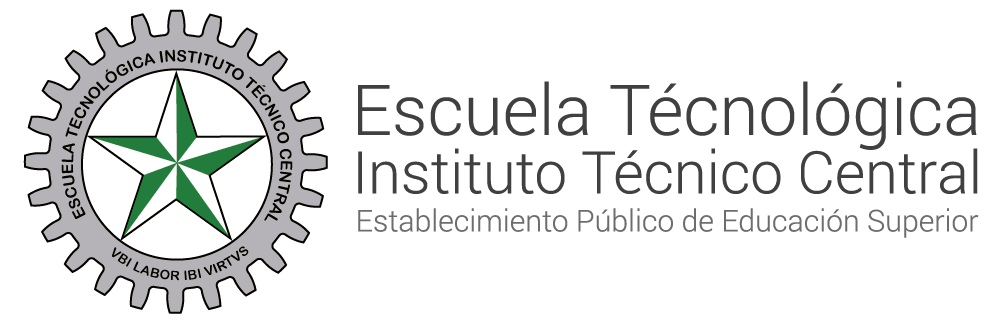

# **Transformada Z**

#### Autor ING. Jheyson Fabian Villavisan Buitrago MS.c

#### Coautor: Yenny Michel Wilches Zarate

**Objetivo:** El objetivo de esta clase es proporcionar a los estudiantes una **comprensión **profunda y práctica de la **Transformada Z** y su relevancia en el análisis y diseño de sistemas lineales e invariantes en el tiempo. Al finalizar la clase, los participantes estarán capacitados para:

Comprender los fundamentos teóricos de la Transformada Z y su relación con el análisis de señales y sistemas discretos.

Dominar los conceptos clave, como la región de convergencia, la relación entre la Transformada Z y la Transformada de Laplace, y las propiedades importantes de la Transformada Z.

# **Escalón unitario.**

- **Definición:**

El escalón unitario, denotado como $u\left(t\right)$, es una función definida como:


$$u\left(t\right)=\left\lbrace \begin{array}{ll}
0 & \textrm{si}\;t<0\\
1 & \textrm{si}\;t\ge 0
\end{array}\right.$$


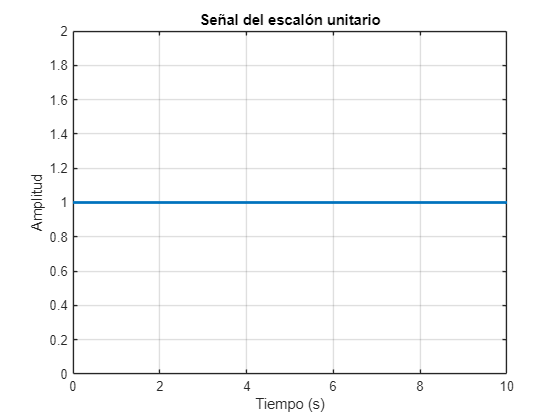

Ts = 0.1; 
t = 0:Ts:10; 
u = ones(size(t)); 
figure;
plot(t, u, 'LineWidth', 2); 
title('Señal del escalón unitario'); 
xlabel('Tiempo (s)'); 
ylabel('Amplitud'); 
grid on;

Para un sistema continuo,** la transformada de Laplace** de una función $f\left(t\right)$ está dada por:


$$u\left(t\right)=$$

$$\int_{-\infty }^{\infty } f\left(t\right)e^{-\textrm{st}} \textrm{dt}$$


Aplicando esto al escalón unitario:


$$u\left(t\right)=\left\lbrace \begin{array}{ll}
0 & \textrm{si}\;t<0\\
1 & \textrm{si}\;t\ge 0
\end{array}\right.$$


Por lo que la integral resultante es la siguiente:


$$U\left(s\right)=$$

$$\int_0^{\infty } u\left(t\right)\cdot e^{-\textrm{st}} \textrm{dt}$$


Resolviendo la integral:


$$U\left(s\right)=$$

$$\int_0^{\infty } 1\cdot e^{-\textrm{st}} \textrm{dt}$$


realizando cambio de variable:


$$u=\textrm{st}$$


resulta:


$$u=-\textrm{st}$$



$$\textrm{du}=-s\;\textrm{dt}$$


reescribiendo la integral:


$$\int_0^{\infty } \frac{e^u }{-s}\textrm{du}$$
 

Finalmente obtenemos:


$${\left|\frac{e^{-\textrm{st}} }{-s}\right|}_0^{\infty }$$



$$U\left(s\right)=\left\lbrack -\frac{1}{s}e^{-\textrm{st}} \right\rbrack$$


Y evaluando en los límites de integración

- Cuando $t\longrightarrow \infty ,e^{-\textrm{st}} \longrightarrow 0\;\textrm{si}\;s>0$

- Cuando $t=0,e^{-\textrm{st}} =1$

Por lo tanto: 


$$\mathit{\mathbf{U}}\left(\mathit{\mathbf{s}}\right)=\frac{1}{\mathit{\mathbf{s}}}$$


## En sistemas discretos,** la transformada Z** se define como:


$$F\left(z\right)=\sum_{k=-\infty }^{\infty } f\left\lbrack k\right\rbrack z^{-k}$$


donde $f\left\lbrack k\right\rbrack$ representa los valores de la señal discreta en instantes $k$ (en este caso el escalón unitario). Para el escalón unitario discreto se tiene **que **$u\left(k\right)=1\;\textrm{para}\;k\ge 0$**:**

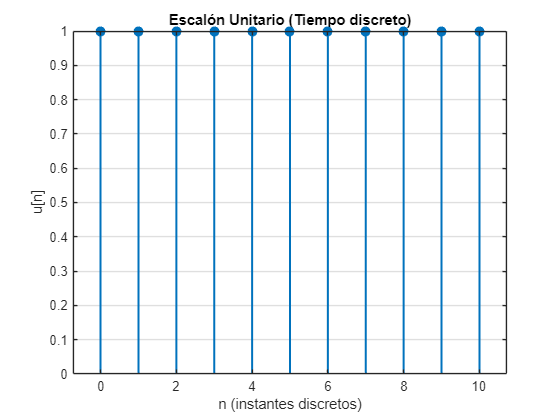

n = 0:10;
u = ones(size(n));
figure;
stem(n, u, 'filled', 'LineWidth', 1.5);
title('Escalón Unitario (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('u[n]');
grid on;


$$U\left(z\right)=\sum_{k=0}^{\infty } 1\cdot z^{-k}$$


Para resolver la trasnformada Z, se tiene en cuenta, la serie geométrica, la cual se define como: 


$$\sum_{n=0}^N r^n =\frac{r^{N+1} -1}{r-1}$$


Considerando lo anterior, se puede reescribir como:

$U\left(z\right)=\sum_{k=0}^{\infty } {\left(\frac{1}{z}\right)}^k$=$\frac{r^{N+1} -1}{r-1}$

Reemplazando $\frac{1}{z}$ en $r$ se obtiene:


$$U\left(z\right)=\frac{{\left(\frac{1}{z}\right)}^{\infty +1} -1}{\frac{1}{z}-1}$$


- Cuando ${\left(\frac{1}{z}\right)}^{\infty +1}$; Cuando se eleva un número $\left|\frac{1}{z}\right|<1$ a potencias crecientes $\left(\infty +1\right)$, el resultado converge hacia $0$. Esto se debe a que multiplicar un número menor que $1$ por sí mismo repetidamente da como resultado un valor cada vez más pequeño. Matemáticamente:


$$\lim_{n\longrightarrow \infty } {\left(\frac{1}{z}\right)}^n =0,\textrm{si}\;\left|\frac{1}{z}\right|<1$$


Por lo tanto:


$$U\left(z\right)=\frac{-1}{z^{-1} -1}$$


Simplificando:


$$\begin{array}{l}
U\left(z\right)=\frac{1}{1-\frac{1}{z}}\\
U\left(z\right)=\frac{1}{\frac{z-1}{z}}\\
\mathit{\mathbf{U}}\left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}}{\mathit{\mathbf{z}}-1}
\end{array}$$


# **Rampa.**

- **Definición:**

La función rampa, denotada como $r\left(t\right)$, es una función definida como:


$$r\left(t\right)=\left\lbrace \begin{array}{ll}
0 & \textrm{si}\;t<0\\
t & \textrm{si}\;t\ge 0
\end{array}\right.$$


Representa un incremento lineal en el tiempo a partir de $t=0\ldotp$

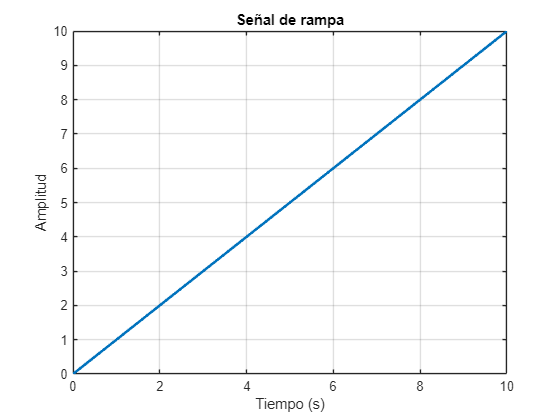

Ts = 0.01; 
t = 0:Ts:10; 
r = t;
figure;
plot(t, r, 'LineWidth', 2);
title('Señal de rampa');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

- **Demostración matemática:**

En sistemas continuos, su **transformada de Laplace** es:


$$R\left(s\right)=\int_0^{\infty } t\cdot e^{-\textrm{st}} \textrm{dt}$$


Esta es una integral por partes, donde:

- Sea $u=t\;\mathrm{y}\;\textrm{du}=e^{-\textrm{st}} \textrm{dt}$

- Entonces, $\textrm{du}=\textrm{dt}\;\mathrm{y}\;v=-\frac{1}{s}e^{-\textrm{st}}$

Por partes: 


$$R\left(s\right)=\left\lbrack -\frac{t}{s}e^{-\textrm{st}} \right\rbrack +\int_0^{\infty } \frac{1}{s}e^{-\textrm{st}} \textrm{dt}$$


- El primer término se evalúa como $0$ porque ${\textrm{te}}^{-\textrm{st}} \longrightarrow 0\;\textrm{cuando}\;t\longrightarrow \infty \;\mathrm{y}\;s>0$

La integral resultante es: 


$$\int_0^{\infty } \frac{1}{s}e^{-\textrm{st}} \textrm{dt}=\frac{1}{s}\cdot \frac{1}{s}$$


Entonces:


$$\mathit{\mathbf{R}}\left(\mathit{\mathbf{s}}\right)=\frac{1}{{\mathit{\mathbf{s}}}^2 }$$


En sistemas digitales, su **transformada Z** es:

Para la rampa discreta, $r\left\lbrack k\right\rbrack =k\;\textrm{para}\;k\ge 0,$ usando la definición de la transformada Z:

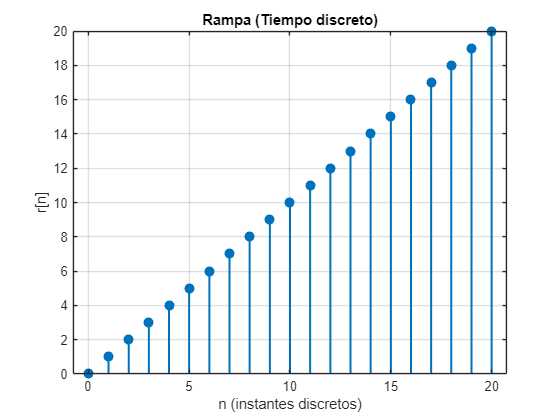

n = 0:20; 
r = n;
figure;
stem(n, r, 'filled', 'LineWidth', 1.5);
title('Rampa (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('r[n]');
grid on;


$$\begin{array}{l}
R\left(z\right)=\sum_{k=0}^{\infty } r\left\lbrack k\right\rbrack \cdot z^{-k} \\
R\left(z\right)=\sum_{k=0}^{\infty } k\cdot z^{-k} 
\end{array}$$


Para resolver, se utiliza una propiedad derivada de la serie geométrica básica:


$$\sum_{k=0}^{\infty } x^k =\frac{1}{1-x}\;\textrm{para}\;\left|x\right|<1$$


Se toma la derivada con respecto a $x$ en ambos lados para introducir el término de $k$:


$$\frac{d}{\textrm{dx}}\left(\sum_{K=0}^{\infty } x^k \right)=\frac{d}{\textrm{dx}}\left(\frac{1}{1-x}\right)$$


Resolviendo:

- En la sección izquierda: 


$$\frac{d}{\textrm{dx}}\left(\sum_{K=0}^{\infty } x^k \right)=\sum_{K=0}^{\infty } {\textrm{kx}}^{k-1}$$


- En la sección derecha: 


$$\frac{d}{\textrm{dx}}\left(\frac{1}{1-x}\right)=\frac{1}{{\left(1-x\right)}^2 }$$


Por lo tanto:


$$\sum_{K=0}^{\infty } {\textrm{kx}}^{k-1} =\frac{1}{{\left(1-x\right)}^2 }$$


Se multiplica por $x$ para ajustar la potencia: 


$$\sum_{K=0}^{\infty } {\textrm{kx}}^k =\frac{x}{{\left(1-x\right)}^2 }$$


En la transformada Z, se obtiene $x=z^{-1} \ldotp$ Sustituyendo:


$$\sum_{K=0}^{\infty } {\textrm{kz}}^{-k} =\frac{z^{-1} }{{\left(1-z^{-1} \right)}^2 }$$


Simplificando:


$$R\left(z\right)=\frac{z^{-1} }{{\left(1-z^{-1} \right)}^2 }$$


Multiplicar el numerador y denominador por $z^2$ para eliminar los términos $z^{-1}$:


$$\mathit{\mathbf{R}}\left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}}{{\left(\mathit{\mathbf{z}}-1\right)}^2 }$$


## Resumen

# Taller

Encuentre las transformadas z de las siguientes funciones.

- 
$$f\left\lbrack k\right\rbrack ={\mathrm{ke}}^{-3k}$$


- 
$$f\left\lbrack k\right\rbrack =k^2 e^{-2k}$$


- 
$$f\left\lbrack k\right\rbrack =k\;\sin \;\left(2k\right)$$


- $f\left\lbrack k\right\rbrack =9k\;\left(2^{k-1} \right)-2^k +3$ $k=0,1,2,3$ Asuma $x\left\lbrack k\right\rbrack =0\;\mathrm{para}\;k<0$

- 
$$f\left\lbrack k\right\rbrack =\frac{1}{a}\left(1-e^{-\mathrm{ak}} \right)$$
